x=50;y=80;g=10;w0=2;w1=1;v0=100;
g1_rhs= @(t,theta0) v0.*cos(theta0).*t

g1_rhs = function_handle with value:
    @(t,theta0)v0.*cos(theta0).*t


g2_rhs= @(t,theta0) v0.*sin(theta0).*t-1/2.*g.*t.^2

g2_rhs = function_handle with value:
    @(t,theta0)v0.*sin(theta0).*t-1/2.*g.*t.^2



g1_lhs= @(t) x+w0*t+w1*t^2;
g2_lhs= @() y;

f1=@(t,theta0) g1_rhs(t,theta0)-g1_lhs(t)

f1 = function_handle with value:
    @(t,theta0)g1_rhs(t,theta0)-g1_lhs(t)


f2=@(t,theta0) g2_rhs(t,theta0)-g2_lhs()

f2 = function_handle with value:
    @(t,theta0)g2_rhs(t,theta0)-g2_lhs()


syms f1s(t,theta0) f2s(t,theta0)
f1s(t,theta0)=sym(f1)

$$f1s(t, theta0) = 100\,t\,\cos\left(\theta_{0}\right)-2\,t-t^{2}-50$$

f2s(t,theta0)=sym(f2)

$$f2s(t, theta0) = -5\,t^{2}+100\,\sin\left(\theta_{0}\right)\,t-80$$

J1s=jacobian([f1s,f2s],[t,theta0])

$$J1s(t, theta0) = \left(\begin{array}{cc} 100\,\cos\left(\theta_{0}\right)-2\,t-2 & -100\,t\,\sin\left(\theta_{0}\right)\\ 100\,\sin\left(\theta_{0}\right)-10\,t & 100\,t\,\cos\left(\theta_{0}\right) \end{array}\right)$$

J=matlabFunction(J1s)

J = function_handle with value:
    @(t,theta0)reshape([t.*-2.0+cos(theta0).*1.0e+2-2.0,t.*-1.0e+1+sin(theta0).*1.0e+2,t.*sin(theta0).*-1.0e+2,t.*cos(theta0).*1.0e+2],[2,2])


F=matlabFunction([f1s;f2s])

F = function_handle with value:
    @(t,theta0)[t.*-2.0+t.*cos(theta0).*1.0e+2-t.^2-5.0e+1;t.*sin(theta0).*1.0e+2-t.^2.*5.0-8.0e+1]


xy=[1;pi/6];error=0.01;num=0;xy_prev=[Inf,Inf];
%xy=[20;pi/6];error=0.01;num=0;xy_prev=[Inf,Inf];

while norm(xy-xy_prev)>error
    xy_prev=xy;
    xy=xy-(J(xy(1),xy(2)))\F(xy(1),xy(2));   
    %xy=xy-inv(J(xy(1),xy(2)))*F(xy(1),xy(2));  
    num=num+1;
end
xy(1)

ans = 1.0019

xy(2)

ans = 1.0133

xy(2)*360/(2*pi)

ans = 58.0570

num

num = 3


g1_lhs(xy(1))

ans = 53.0076

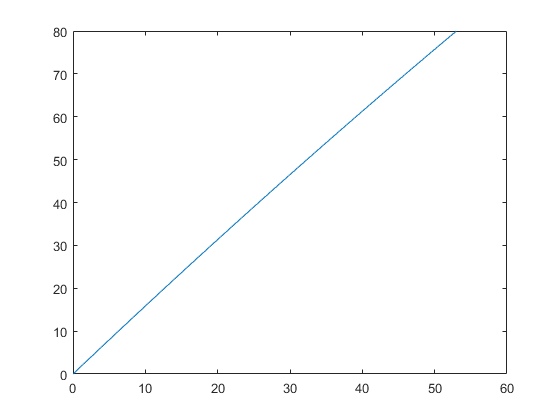

tt = linspace(0,xy(1),100) ;
x=g1_rhs(tt,xy(2));
y=g2_rhs(tt,xy(2));
plot(x,y)